clc
clear

% Reaction Engineering - PFR preliminary calculations
% File written by Elias Petrenko
% Last modified 12/04/2024
%
% components present in solution
% A - H18-DBT
% B - H0-DBT
% C - H2
%
%Stoichiometry for dehydrogenation reaction
%   A --> B + 9H2

% Variable dictionary
% k_gcat = Rate constant (L min-1 gcat-1)
% v0 = volumetric flowrate (m3/min)
% DensityA = Density H18-DBT (m3/kg)
% Vol_A = Volume of H18-DBT inital (m3)
% Mol_A = Moles of H18-DBT inital (mol)
% mMassA = Molar mass of H18-DBT (mol/kg)
% MassA = Mass of H18-DBT inital (kg)
%X_tar = Target conversion in PFR (n/a)
%CA0 = Inital concentration of H18-DBT (mol/m3)
%FA0 = Molar flowrate of H18-DBT (mol/min)

global v0 k_gcat

%input variables 
%k_gcat=8.63E-05; % k value 5%wt/Pt from literature(L min-1 gcat-1) 
k_gcat=8.078E-05; % k value 1%wt/Pt from literature (L min-1 gcat-1) 
%k_gcat=3.16898E-05; % k value 0.3%wt/Pt from literature (L min-1 gcat-1)
v0=0.094;           % (m3/min) 
MassA=2900000;      % (kg)
DensityA=844;       %(kg/m3)
mMassA=0.2904;      %(mol/kg)
X_tar=0.99;         %target conversion
Fa0=(v0*DensityA)/(mMassA); %mol/min

%Calculating inital volume and mol of DBTH18 to get inital concentration
Vol_A=MassA/DensityA; % (m3)
Mol_A=MassA/mMassA;   % (mol)
CA0=Mol_A/Vol_A;% (mol/m3)

%Time to process all volume of DBT
ProcessTime=Vol_A/v0 %[min]

ProcessTime = 3.6553e+04


%Number of reactors to process all H18-DBT in 6hours
Time=360;  %min
N_reactors=(ProcessTime/Time)-((ProcessTime/Time)-100); %Rounding to nearest 100


ODE solving for mass of catalyst in PFR

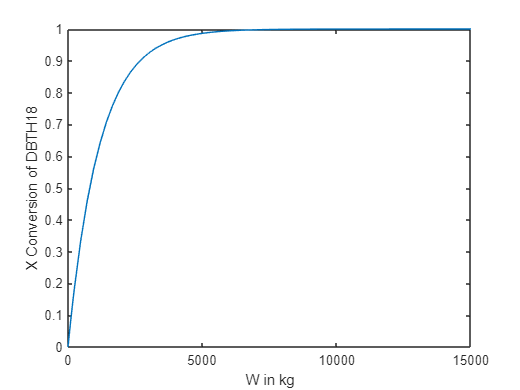

%Solving for mass of catalyst

%Inital values concentration (mol/m3)
Cinitalcat=CA0;

% initial conditions for solving differential equation
% Defining the mass of catalyst for which the approximate solution 
% should be determined

W0 = 0;             % (g)
W_max = 15000000;    % (g)
W_span = [W0,W_max]; %(g)

% Now solve the ODE
%W = Mass of catalyst (g)
%C = Concentration of H18-DBT (mol/m3)

[W,C] = ode45(@mass_catalst,W_span,Cinitalcat);

%Converting to kg
W_kg=W/1000;
%Converting to conversion of H18-DBT to H0-DBT
XAcat=1-(C/CA0);

%Plotting weight of catalyst vs conversion
figure(1)
plot(W_kg,XAcat)
xlabel('W in kg')
ylabel('X Conversion of DBTH18')


% finding weight of catalyst when conversion > X_tar
index = find(XAcat > X_tar, 1, 'first');
Weight_cat=W_kg(index);
fprintf('Weight of catalyst in one PBR: %.0f kg', Weight_cat)

Weight of catalyst in one PBR: 5534 kg


% Working out the cost of catalyst
cost_Pt=27; %Euro per gram of Pt
Pt_fraction=0.01; % Percentage Pt in catalyst
Cost_catalyst=(Weight_cat*1000*Pt_fraction*cost_Pt)/1e6;
fprintf('Cost of catalyst in one PBR: %.2f Million Euro', Cost_catalyst);

Cost of catalyst in one PBR: 1.49 Million Euro

All_cat=Weight_cat*100;
Cost_all_catalyst=(All_cat*1000*Pt_fraction*cost_Pt)/1e6;
fprintf('Cost of catalyst in one PBR: %.0f Million Euro', Cost_all_catalyst);

Cost of catalyst in one PBR: 149 Million Euro


%Volume of one reactor
DenCatbulk=1440;% density of bulk of catalyst (kg/m3)
V_PBR=Weight_cat/DenCatbulk;
fprintf('Volume of one PBR: %.2f m3', V_PBR)

Volume of one PBR: 3.84 m3

Ergun Equation

%Variables
Por=0.4; %Porosity (n/a)
visc=4.5e-4;  %Viscosity (kg/m s)
r=1;     %Radius of PFR (m) --- Assumption
Area=pi*r*r;  %Area of PFR  (m2)
u=(v0*DensityA)/(60*Area)  %superficial velocity (m/s)

u = 0.4209

G=u*DensityA; %superficial mass velocity (kg/m2 s)

% Dp = Catalyst particle diameter
% Define range of Dp values
Dp_range = [0.001:0.001:0.1];

% Initialize empty array to store pressure gradients
dPdz_values = [];

% Loop through different Dp values
for i = 1:length(Dp_range)
  % Update Dp value
  Dp = Dp_range(i);
  
  % Recalculate dPdz
  PartA = G/(DensityA*Dp)*((1-Por)/(Por^3));
  PartB = ((150*(1-Por)*visc)/Dp) + 1.75*G;
  dPdz = PartA*PartB;
  
  % Store pressure gradient for current Dp
  dPdz_values(i) = dPdz;
  kPa=dPdz_values/1000;
end



%Effectiveness factor calculation
De=2.357E-10; %Diffusivity (m2/s) @300C'
k_rate=1.8954e-5 %rate constant (L/min gcat) @300C'

k_rate = 1.8954e-05

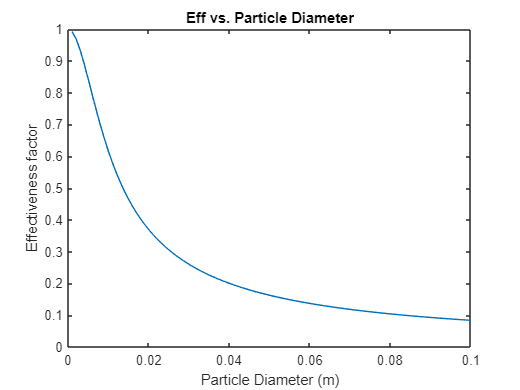

DenCatbul_g=DenCatbulk*1000; % density of bulk of catalyst (kg/m3 to g/m3)
k__=(k_rate*0.001*DenCatbul_g)/60; %(m3ofH18-DBT/m3ofcatalyst sec)

% Loop through different Dp values
for i = 1:length(Dp_range)
  % Update Dp value
  Dp = Dp_range(i);
  
  % Recalculate dPdz
  Thiele=(Dp/4)*((k__/De)^0.5);
  eff=(3/Thiele^2)*(Thiele*coth(Thiele)-1);
  % Store pressure gradient for current Dp
  Eff_values(i) = eff;
  
end

%Plot results
plot(Dp_range, Eff_values)
xlabel('Particle Diameter (m)')
ylabel('Effectiveness factor')
title('Eff vs. Particle Diameter')

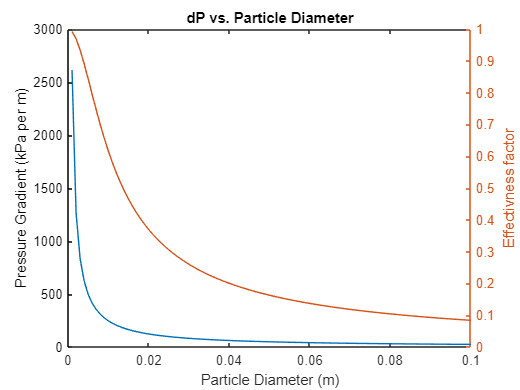



% Plot the results
plot(Dp_range, kPa)
xlabel('Particle Diameter (m)')
ylabel('Pressure Gradient (kPa per m)')
title('dP vs. Particle Diameter')

% After plotting the first equation (pressure gradient)
hold on

% Create a second y-axis on the right side
yyaxis right

% Plot the second equation results on the new y-axis
plot(Dp_range, Eff_values);

% Set labels and title for the second y-axis
ylabel('Effectivness factor');



%transposing and collecting results so can easily export into Excel
ExcelDP=Dp_range.';
ExcelEff=Eff_values.';
ExcelKPa=kPa.';
ExcelExport=[ExcelDP,ExcelKPa,ExcelEff];


ODE function for conversion of DBTH18 vs Weight of catalyst for PFR

function dC_dW = mass_catalst(W,C)

global v0 k_gcat

%Variables
%kcat = Rate constant w.r.t. catalyst weight (L min-1 gcat-1)

% components present in solution
% A - H18-DBT
% B - H0-DBT
% C - H2

% Changing units of k_gcat (L min-1 gcat-1)to (m3/min-1 gcat-1)
kcatm3 = k_gcat*0.001; % (m3/min-1 gcat-1)


% Rate of reaction w.r.t. H18-DBT
rA_=kcatm3*C;  %Rate (mol min-1 gcat-1)

% ODE for each component
dCA_dW=-rA_/v0; %Change in concentration H18-DBT w.r.t mass of catalyst (mol m-3 gcat-1)


% Summarising ODEs
dC_dW = dCA_dW;

end

